# Effects of amount of data 

Does increasing the length of the timeseries lead to better pruning in simulations where only one node is stimulated?

stim_options = get_default_stim_options("task");

### Long infrequent stimulation to hub node

stim_options.stim_node = 2;
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end
num_subj = 20;
DCM_all_short  = cell(num_subj, 1);
options_all_short  = cell(num_subj, 1);
output_all_short  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all_short{i}, options_all_short{i}] = make_task_fmri(stim_options);
    options_all_short{i}.p0_all = sum(sum(logical(DCM_all_short{i}.Tp.A)))/size(DCM_all_short{i}.Tp.A,1)^2; %set to true sparsity
    DCM_all_short{i}.M.noprint = 1;
    [output_all_short{i}, options_all_short{i}] = tapas_rdcm_estimate(DCM_all_short{i}, 's', options_all_short{i}, 2);
end

Increase amount of data 10-fold

stim_options.T = stim_options.T*10;

num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end
num_subj = 20;
DCM_all_long  = cell(num_subj, 1);
options_all_long  = cell(num_subj, 1);
output_all_long  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all_long{i}, options_all_long{i}] = make_task_fmri(stim_options);
    options_all_long{i}.p0_all = sum(sum(logical(DCM_all_long{i}.Tp.A)))/size(DCM_all_long{i}.Tp.A,1)^2; %set to true sparsity
    DCM_all_long{i}.M.noprint = 1;
    [output_all_long{i}, options_all_long{i}] = tapas_rdcm_estimate(DCM_all_long{i}, 's', options_all_long{i}, 2);
end

Plot output.

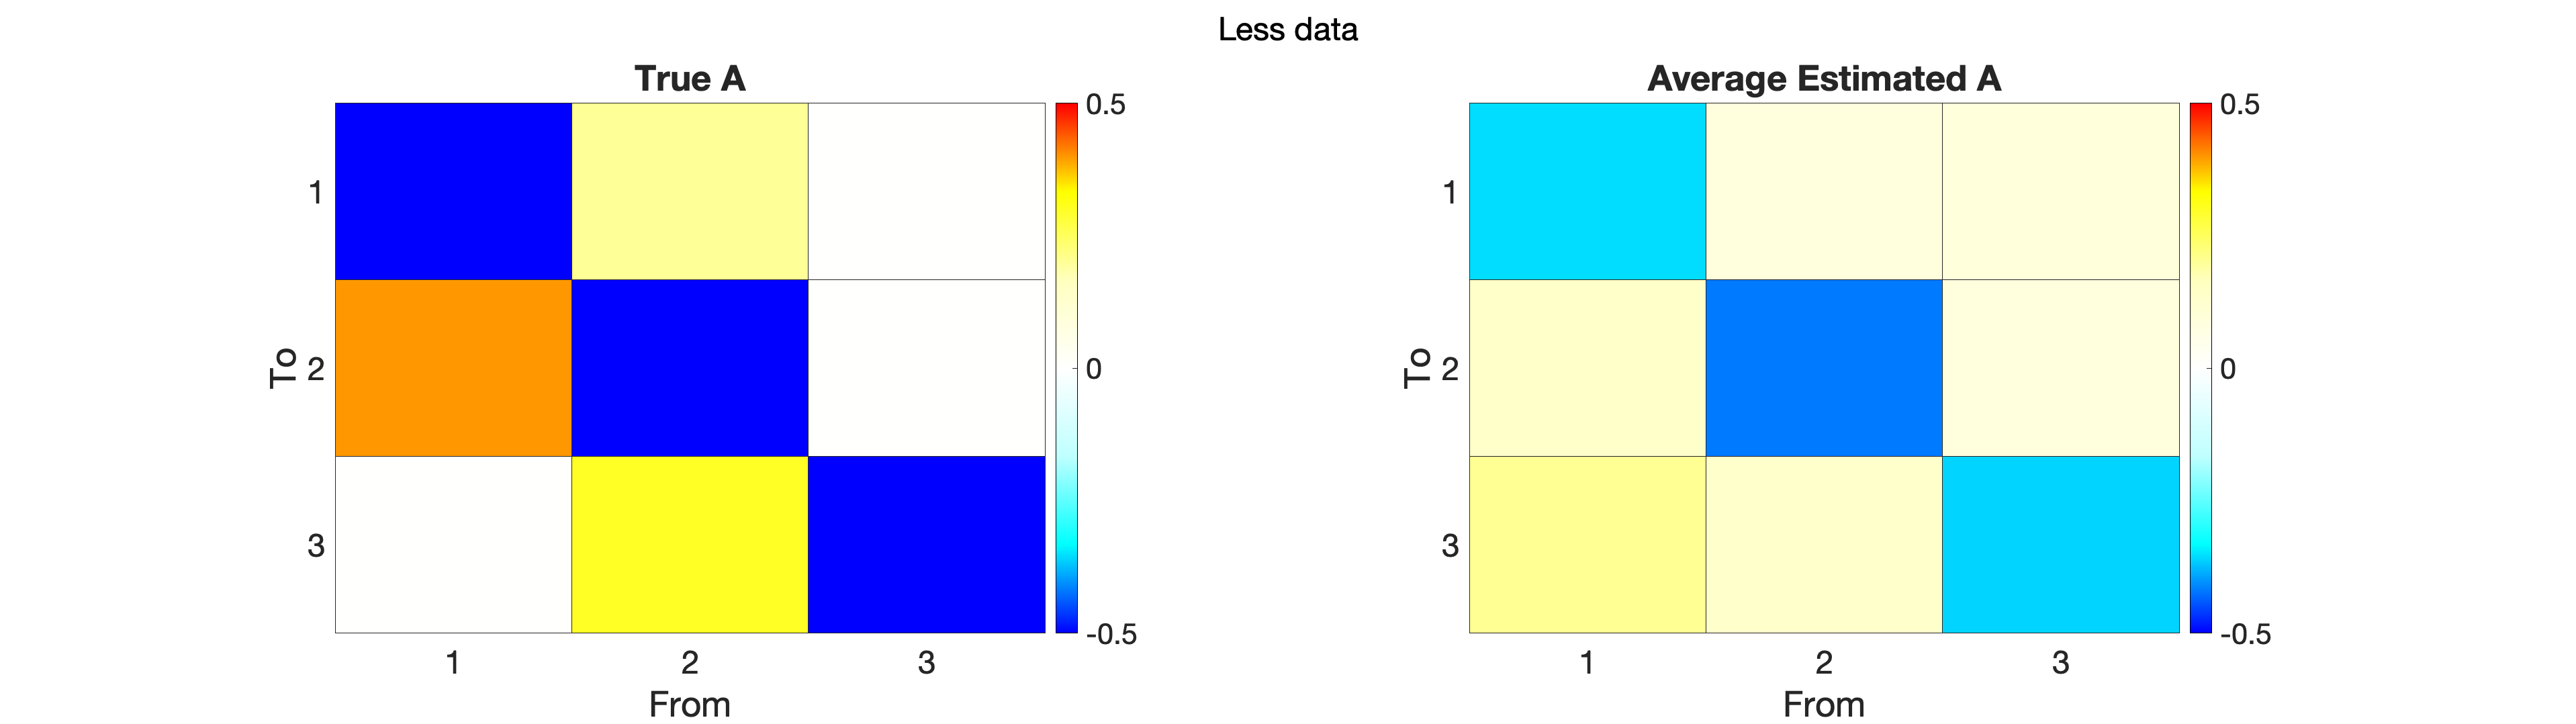

plot_true_est_connectivity(DCM_all_short{1}, output_all_short, 1)
t = sgtitle("Less data");
t.FontSize = 24;

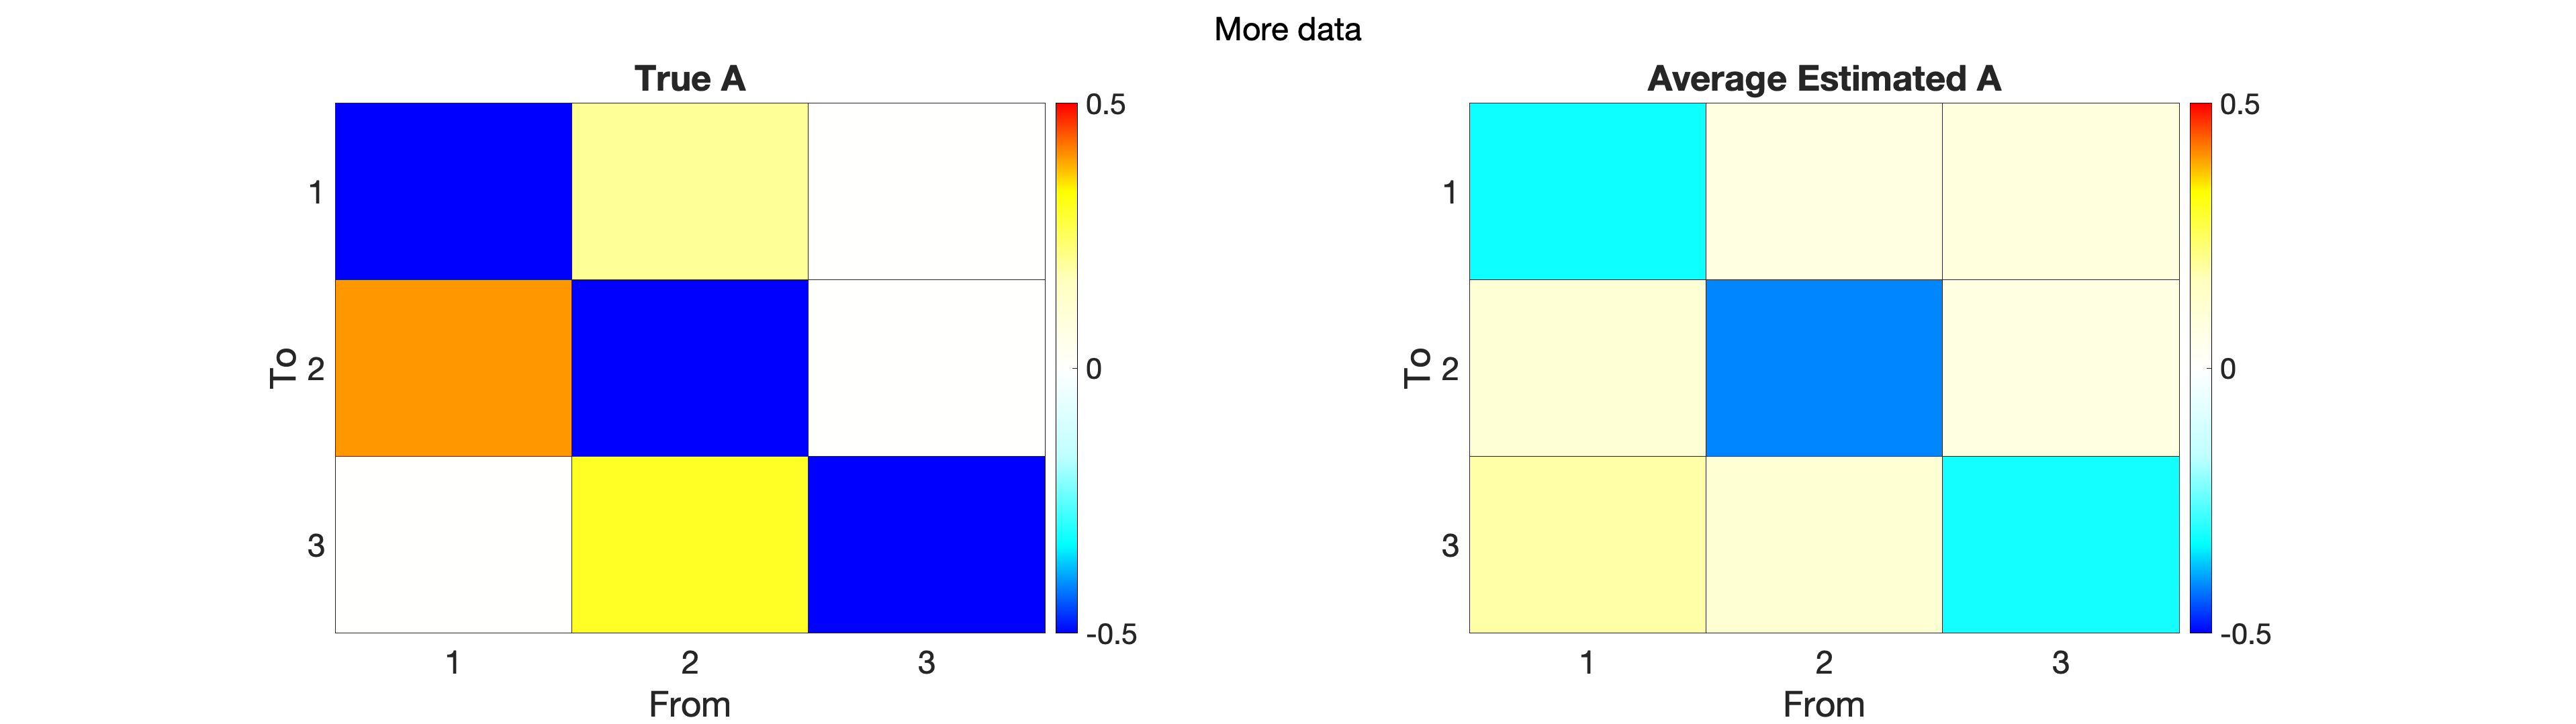


plot_true_est_connectivity(DCM_all_long{1}, output_all_long, 1)
t = sgtitle("More data");
t.FontSize = 24;

Confirm that the two estimated matrices are not identical

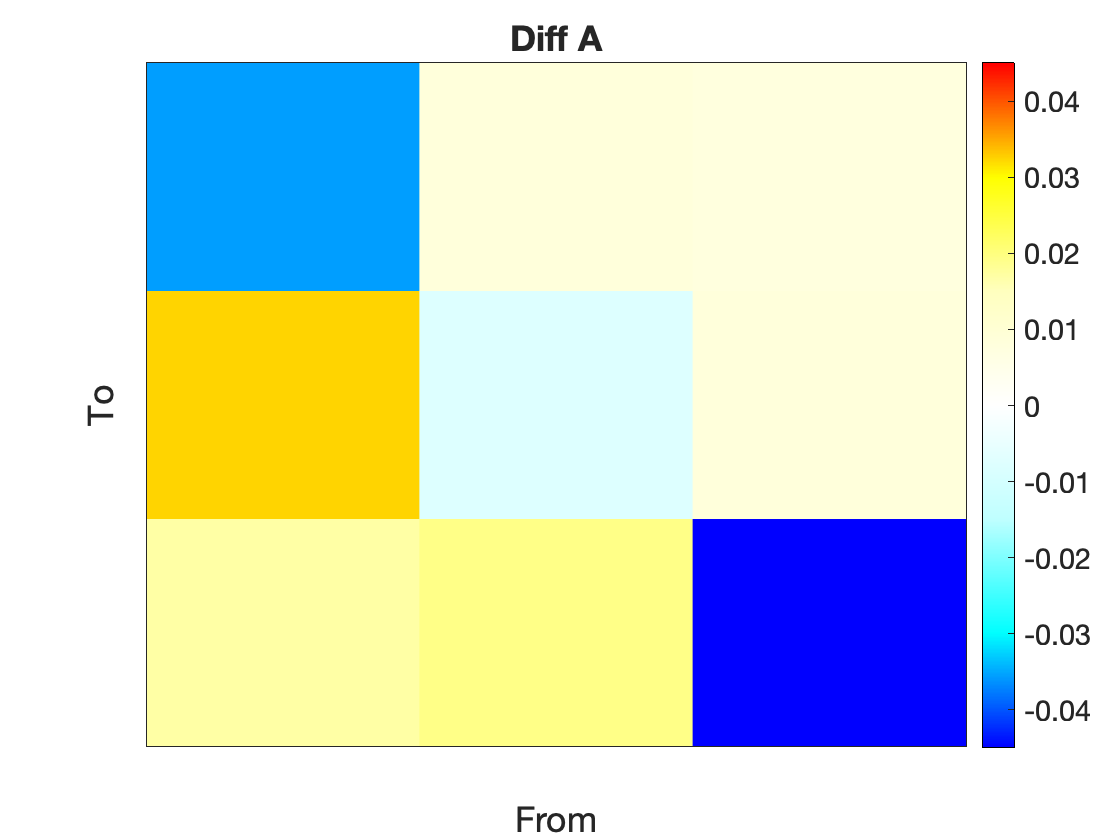

cur_as = cellfun(@(c) {c.Ep.A}, output_all_short);
mean_a_short = mean(cat(3, cur_as{:}), 3);

cur_as = cellfun(@(c) {c.Ep.A}, output_all_long);
mean_a_long = mean(cat(3, cur_as{:}), 3);

diff_A = mean_a_short - mean_a_long;

clf
figure
plot_connectivity(diff_A, 1);
title("Diff A"); 
ax = gca;
ax.FontSize = 16;

### Short frequent stimulation to hub node

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end
num_subj = 20;
DCM_all_short  = cell(num_subj, 1);
options_all_short  = cell(num_subj, 1);
output_all_short  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all_short{i}, options_all_short{i}] = make_task_fmri(stim_options);
    options_all_short{i}.p0_all = sum(sum(logical(DCM_all_short{i}.Tp.A)))/size(DCM_all_short{i}.Tp.A,1)^2; %set to true sparsity
    DCM_all_short{i}.M.noprint = 1;
    [output_all_short{i}, options_all_short{i}] = tapas_rdcm_estimate(DCM_all_short{i}, 's', options_all_short{i}, 2);
end

Increase amount of data 10 fold

stim_options.T = stim_options.T*10;

num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end
num_subj = 20;
DCM_all_long  = cell(num_subj, 1);
options_all_long  = cell(num_subj, 1);
output_all_long  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all_long{i}, options_all_long{i}] = make_task_fmri(stim_options);
    options_all_long{i}.p0_all = sum(sum(logical(DCM_all_long{i}.Tp.A)))/size(DCM_all_long{i}.Tp.A,1)^2; %set to true sparsity
    DCM_all_long{i}.M.noprint = 1;
    [output_all_long{i}, options_all_long{i}] = tapas_rdcm_estimate(DCM_all_long{i}, 's', options_all_long{i}, 2);
end

Plot output. The average estimated connectivity matrix still had very low selectivity.

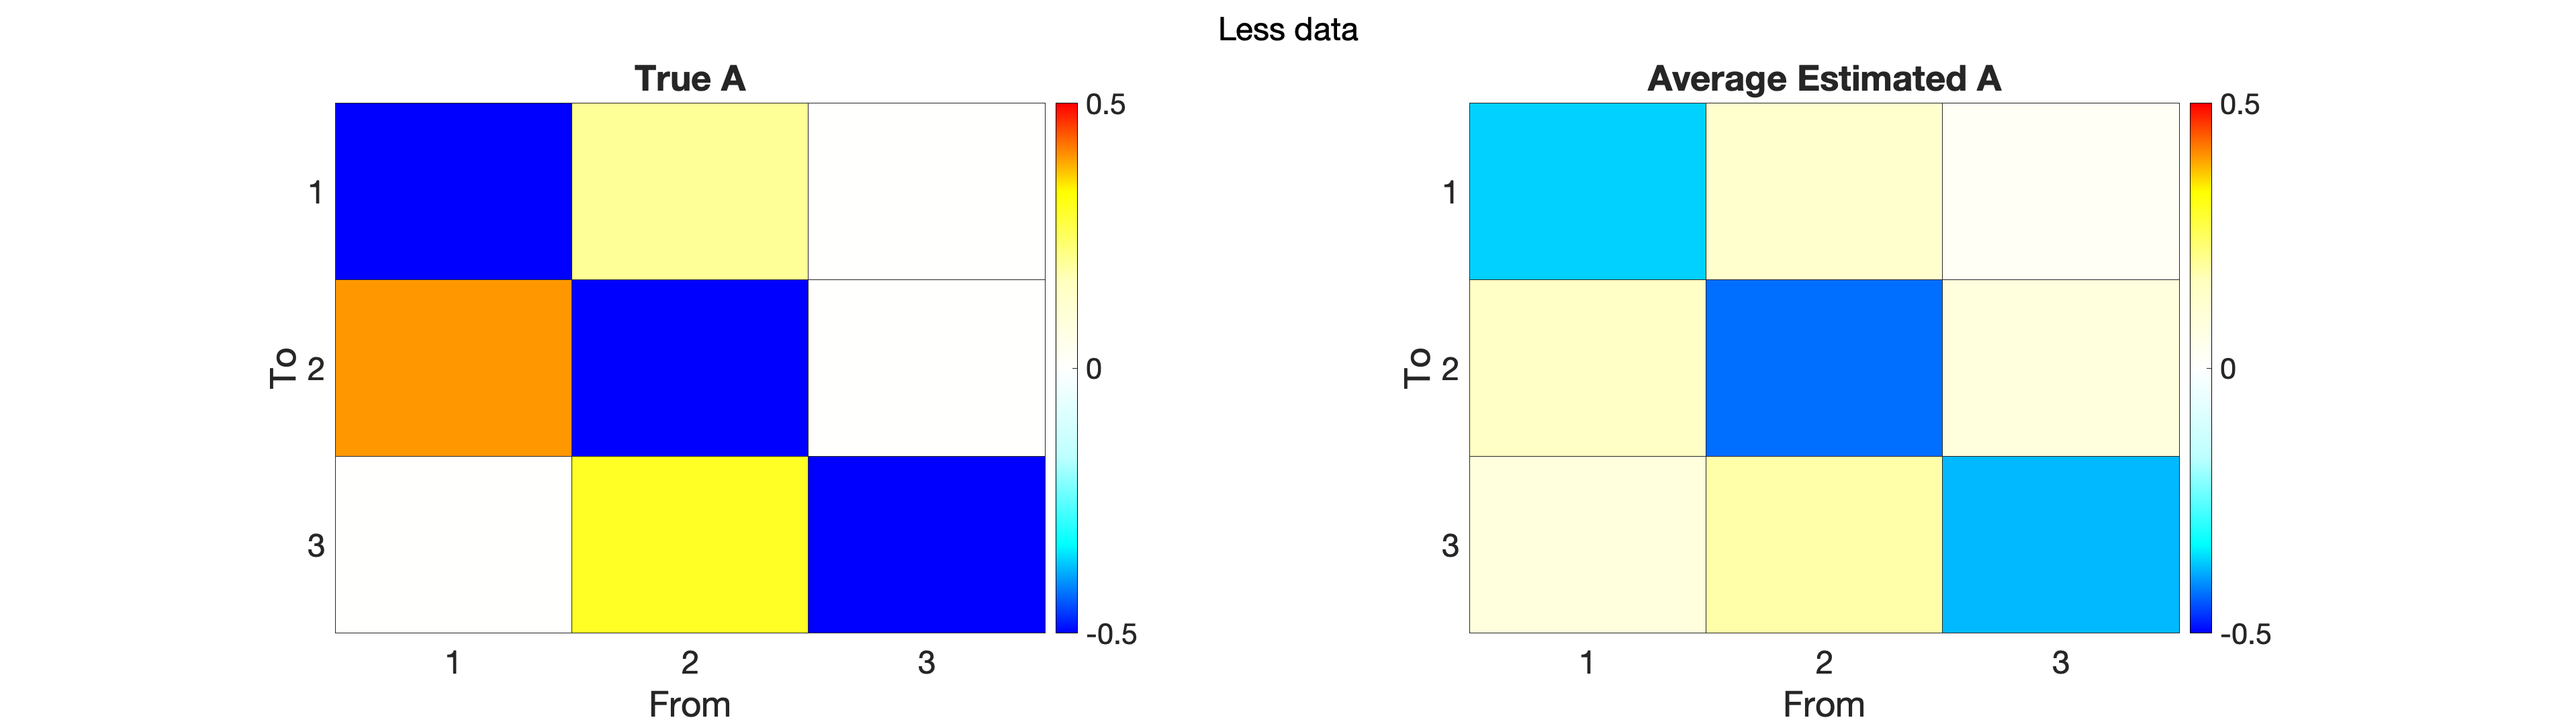

plot_true_est_connectivity(DCM_all_short{1}, output_all_short, 1)
t = sgtitle("Less data");
t.FontSize = 24;

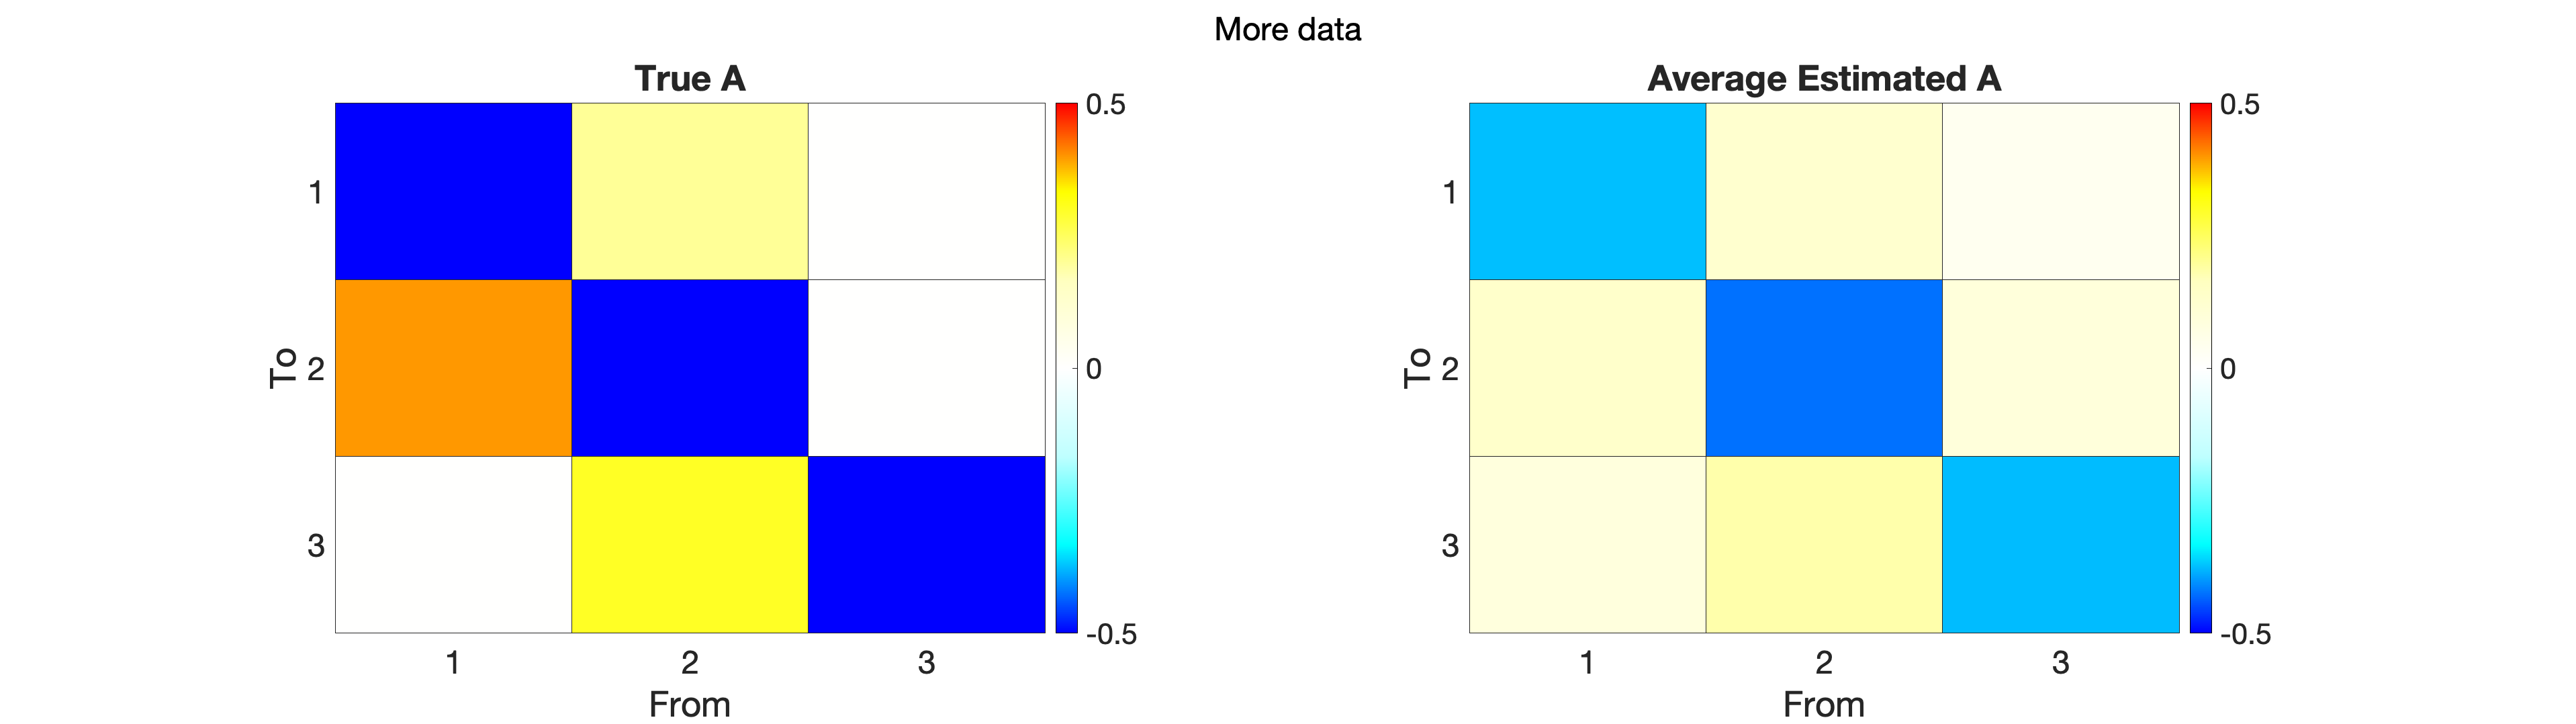


plot_true_est_connectivity(DCM_all_long{1}, output_all_long, 1)
t = sgtitle("More data");
t.FontSize = 24;

Confirm that the two estimated matrices are not identical

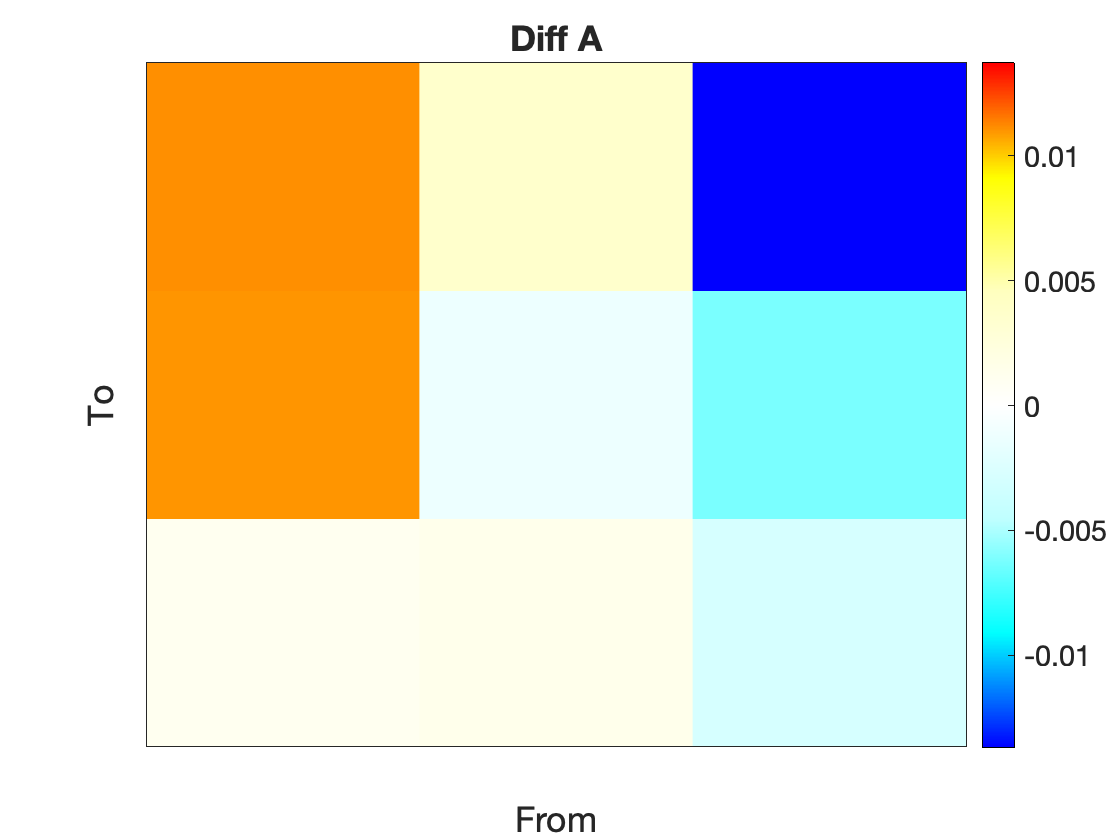

cur_as = cellfun(@(c) {c.Ep.A}, output_all_short);
mean_a_short = mean(cat(3, cur_as{:}), 3);

cur_as = cellfun(@(c) {c.Ep.A}, output_all_long);
mean_a_long = mean(cat(3, cur_as{:}), 3);

diff_A = mean_a_short - mean_a_long;

clf
figure
plot_connectivity(diff_A, 1);
title("Diff A"); 
ax = gca;
ax.FontSize = 16;